# Limites Mecanicos

En este archivo se calculan los limites maximos y minimos a los que cada robot puede

acceder, teniendo en cuenta sus limitaciones mecanicas y longitudes de eslabones

## Scara 3 Grados De Libertad (P2R)

El limite en el eje Z esta estipulado por el valor minimo y maximo de la juntura prismatica

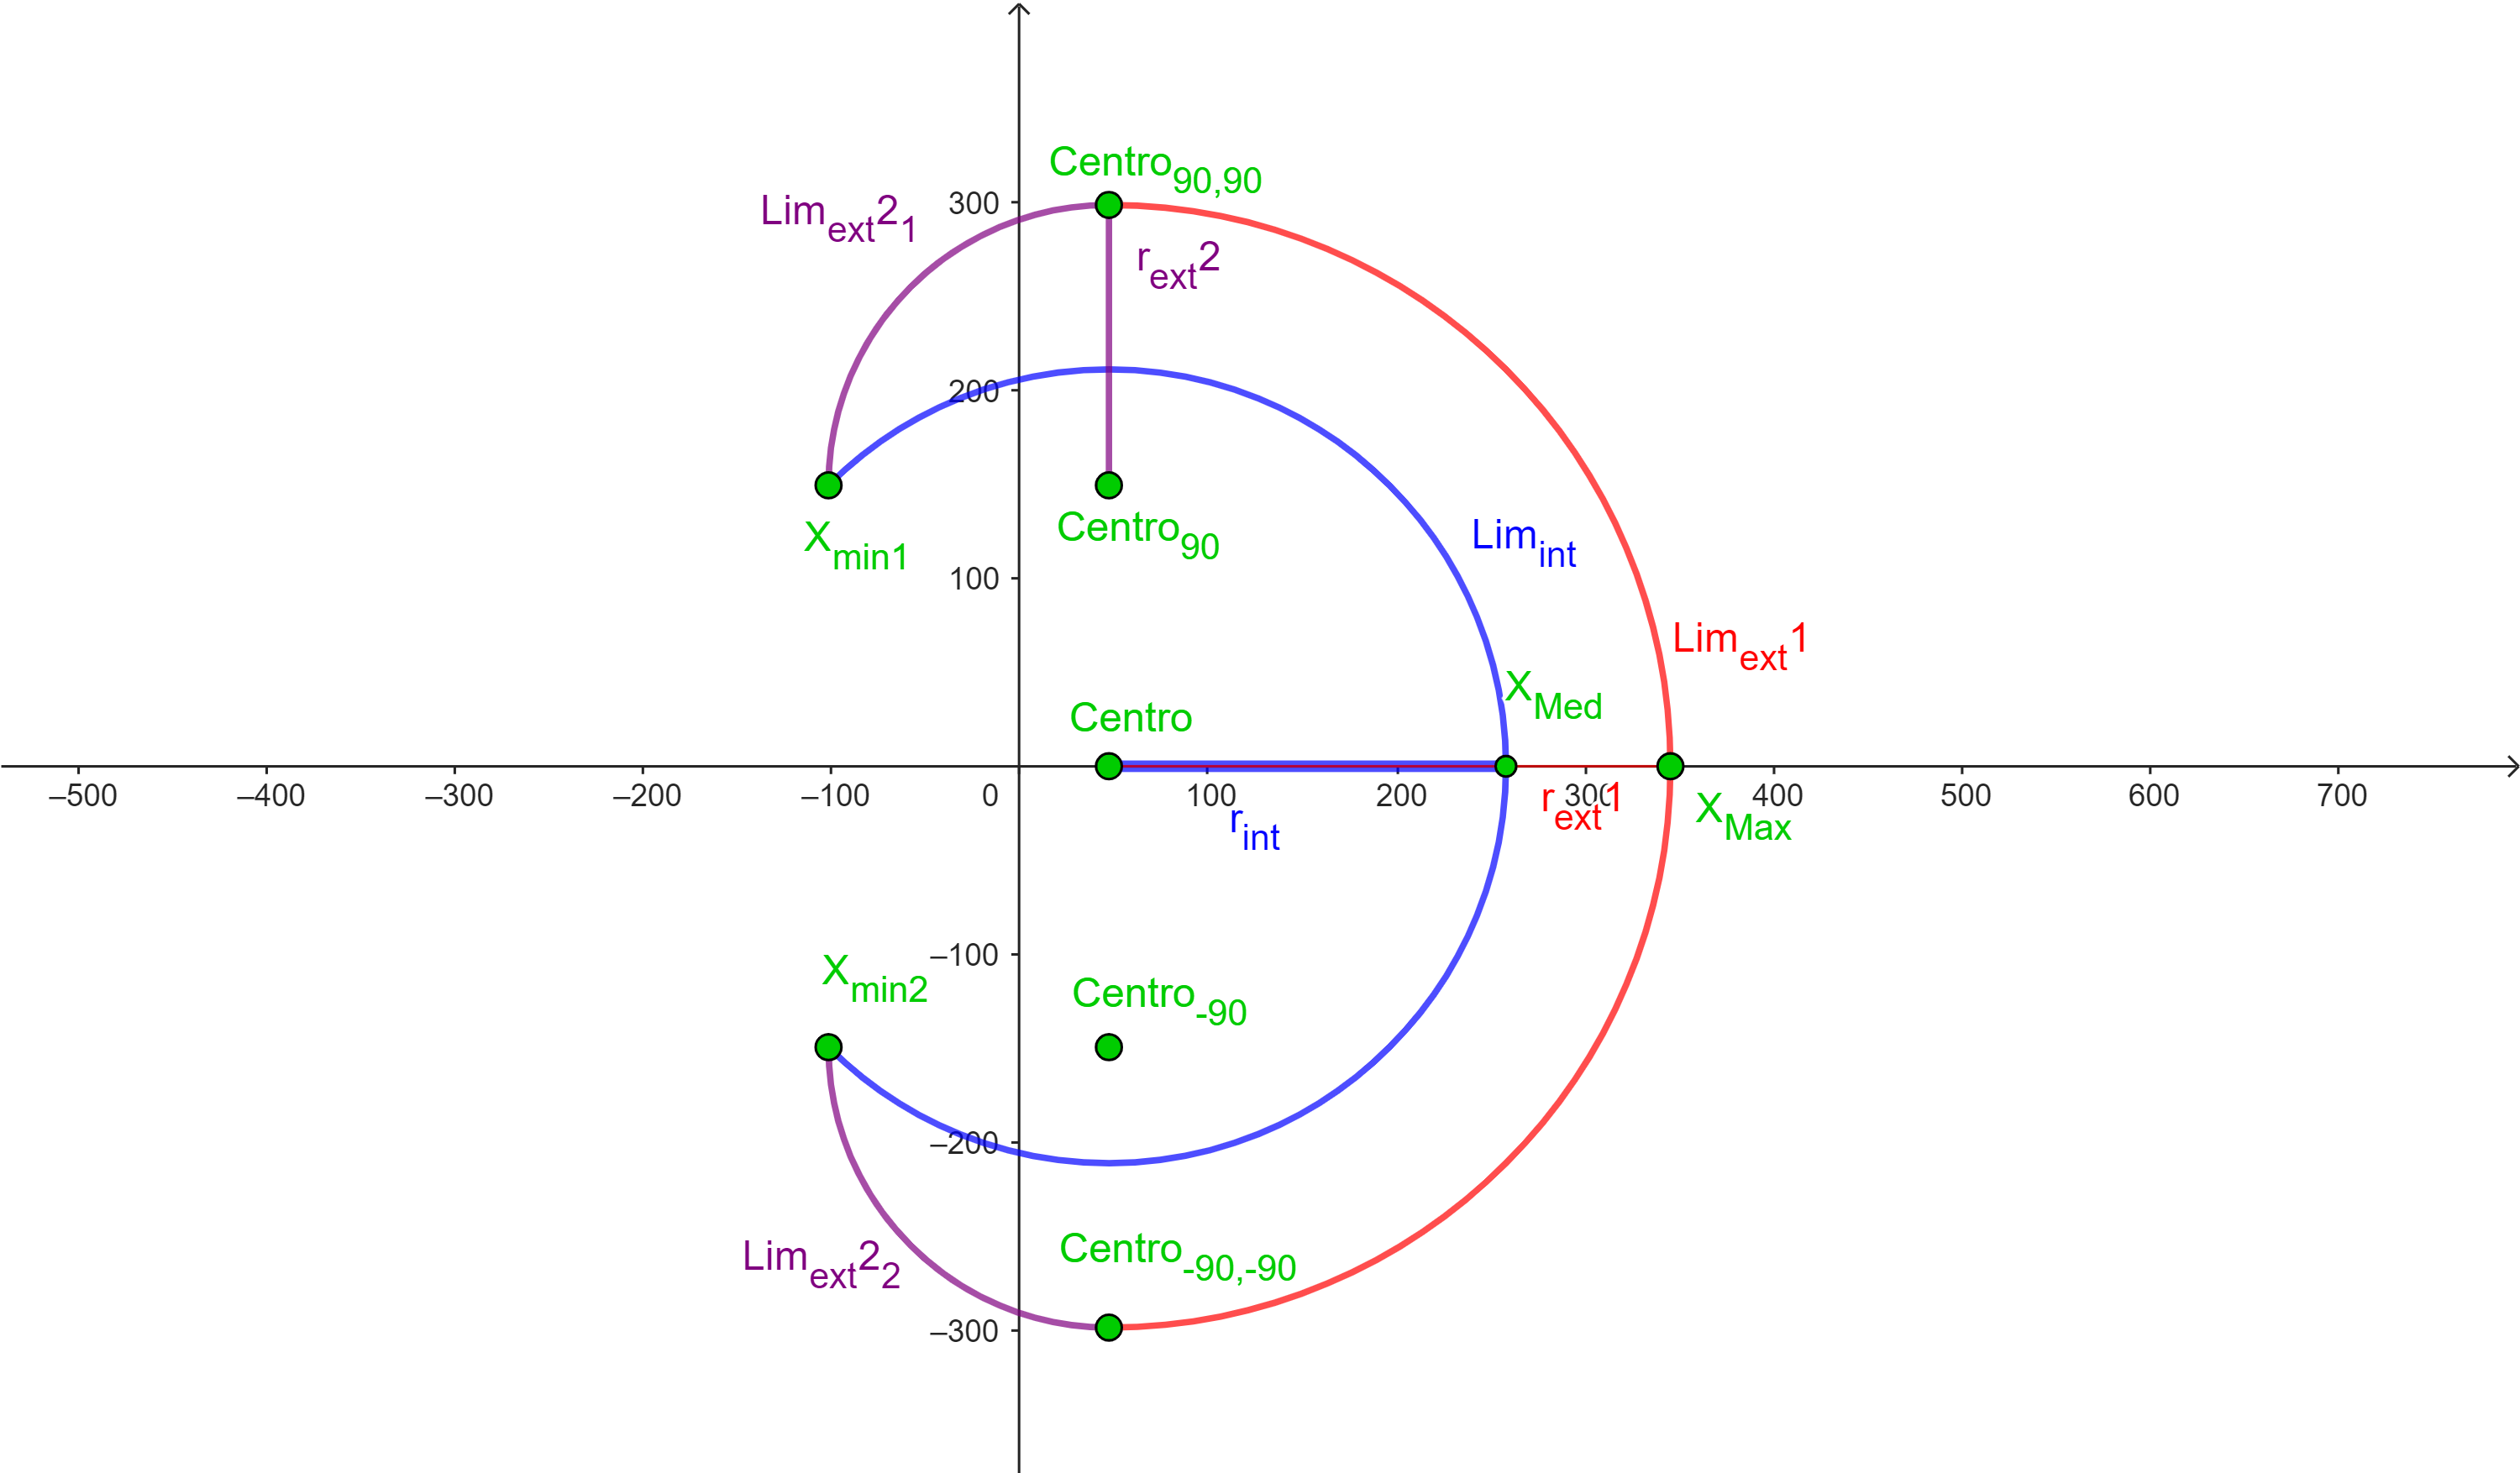

centro=47.3

centro = 47.3000

Xmin=-101.5

Xmin = -101.5000

Xmax=345.2

Xmax = 345.2000

Xmedio=257.95

Xmedio = 257.9500

X=269

X = 269

yext1=sqrt((297.9)^2-(X-47.3)^2);      %Cuando X>Xmedio     
yint=sqrt((210.65)^2-(X-47.3)^2);     %Cuando Centro<=X<Xmedio
yext2=sqrt((148.8)^2-(X-47.3)^2)+149.1; %Cuando Xmin<X<centro
if X>=Xmax
    y=0
elseif X>Xmedio
    ysup=yext1
    yinf=-yext1  
elseif (X>=centro && X<Xmedio)
    ysup=yext1
    yinf=yint
elseif (X<centro && X>Xmin)
    ysup=yext2
    yinf=yint
else 
    ysup=yext2
    yinf=-yext2
end

ysup = 198.9812

yinf = -198.9812

## Antropomórfico sin codo (3R)

El espacio de trabajo es el comprendido entre las dos esferas, considerando tramos distintos en el eje Z.

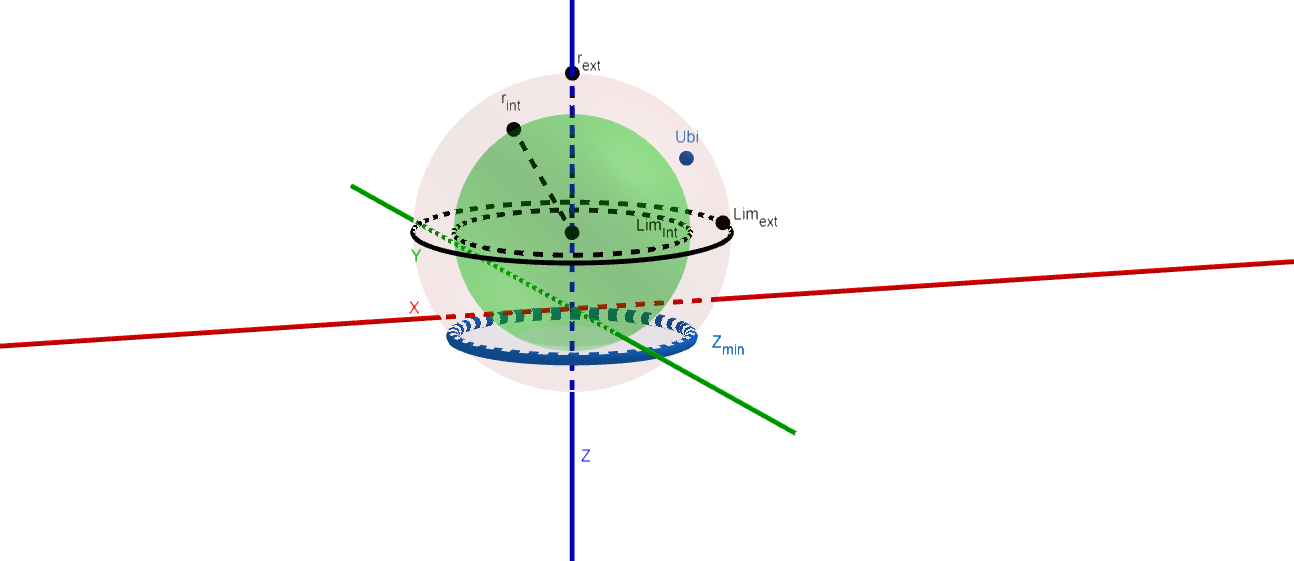

X=-180.5

X = -180.5000

y=sqrt((197.21)^2-(X)^2) 

y = 79.4452

Y=59.5;
Zmin=-34.64;
Lim_Int=146.63;
Ubi=sqrt(X^2+Y^2)

Ubi = 190.0539

if Ubi>Lim_Interior
    zext=sqrt((197.21)^2-X^2-(Y)^2)+95.91 
    zext2=-sqrt((197.21)^2-X^2-(Y)^2)+95.91
    if zext2<=Zmin
        zext2=Zmin
    end
elseif Ubi<Lim_Interior
    zext=sqrt((197.21)^2-(X)^2-(Y)^2)+95.91 
    zext2=-sqrt((197.21)^2-(X)^2-(Y)^2)+95.91
    if zext2<=Zmin
        zext2=Zmin
    end
    zint=sqrt((146.63)^2-(X)^2-(Y)^2)+95.91 
    zint2=-sqrt((146.63)^2-(X)^2-(Y)^2)+95.91 
    if zint2<=Zmin
        zint2=Zmin
    end
end

zext = 148.5530

zext2 = 43.2670